Case 14 nodes, 1.000000e-01 random_load_cv


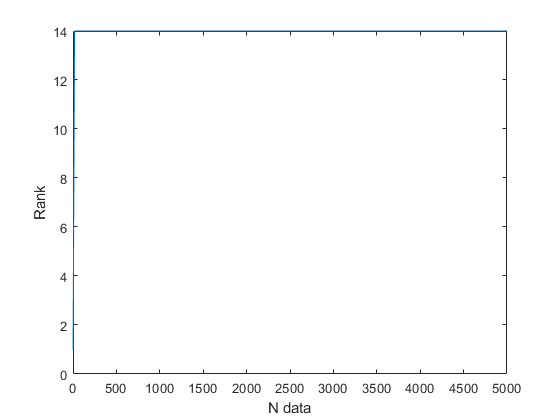

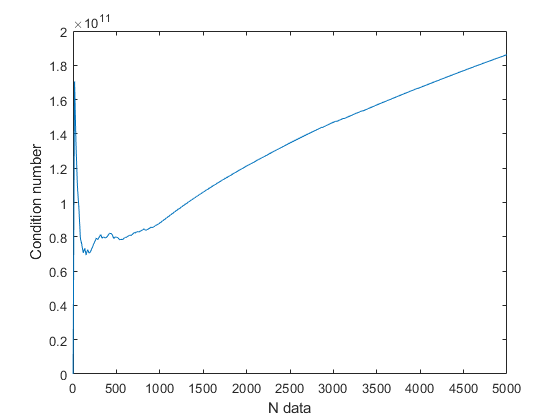

Case 14 nodes, 3.000000e-01 random_load_cv


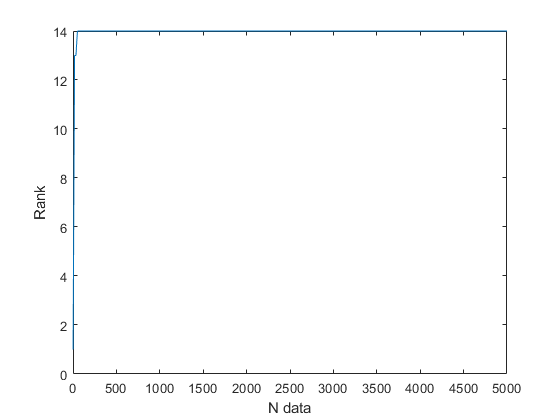

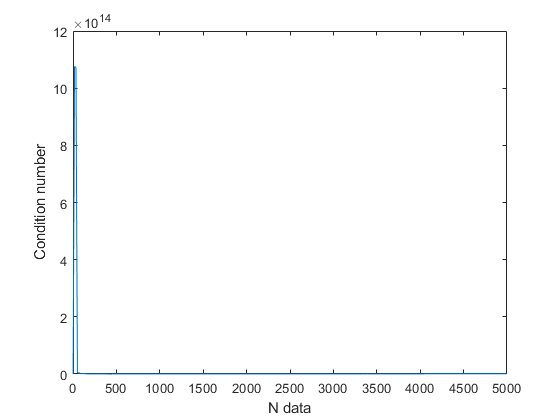

close all; clc; clear all;

analysis(14, [0.1, 0.3], 300)

Case 57 nodes, 1.000000e-01 random_load_cv


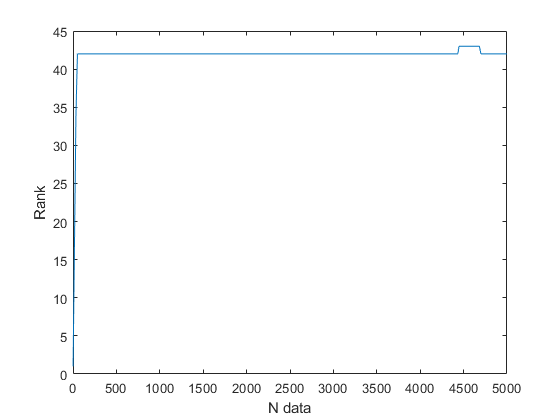

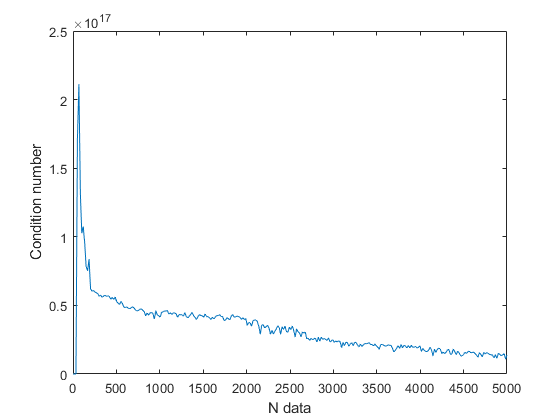

Case 57 nodes, 2.000000e-01 random_load_cv


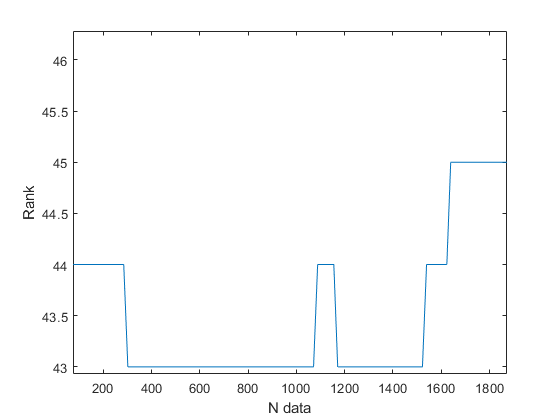

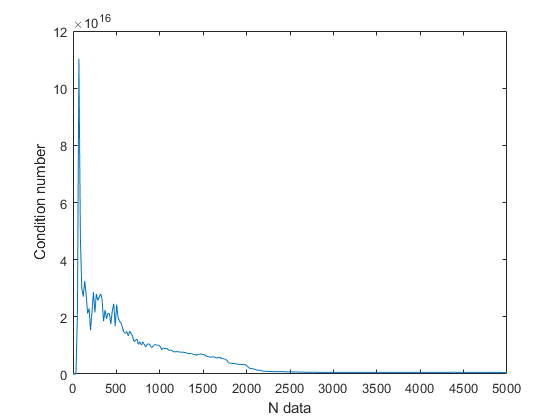

Case 57 nodes, 3.000000e-01 random_load_cv


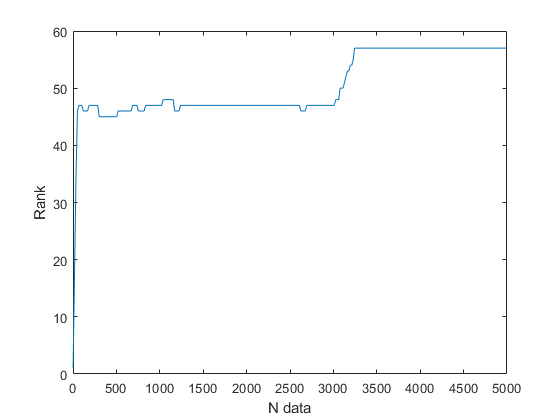

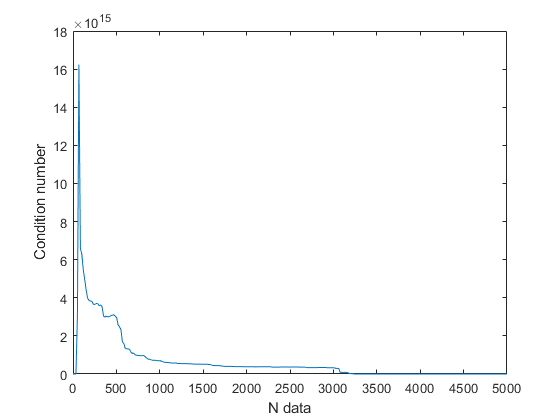

Case 57 nodes, 4.000000e-01 random_load_cv


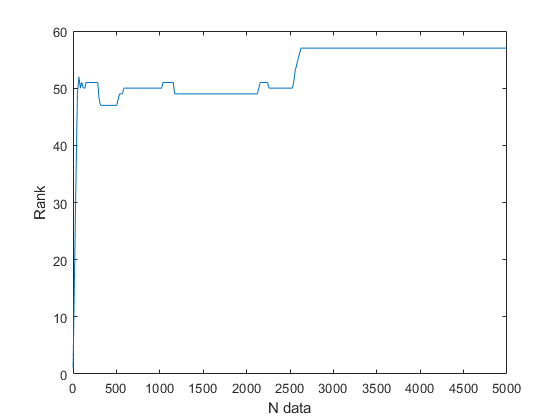

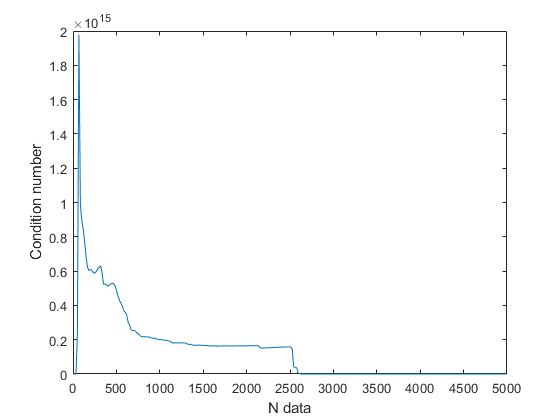


analysis(57, [0.1, 0.2, .3, .4], 300)

Case 118 nodes, 1.000000e-01 random_load_cv


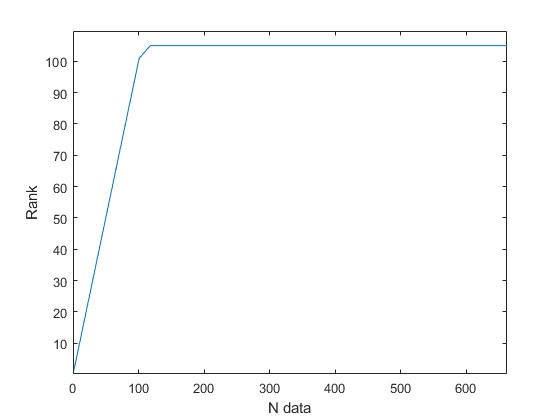

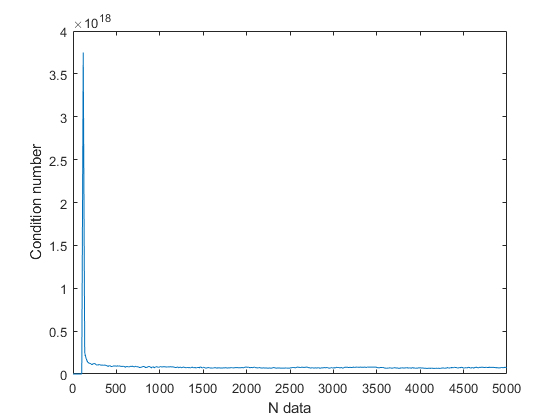

% analysis(118, [0.1], 300)

function [] = analysis(n, load_cv, n_points)
    for i = load_cv
        disp(sprintf('Case %d nodes, %d random_load_cv', n, i))
        bus_voltage = load(sprintf('save_%d_%d.mat', n, i)).bus_voltage;
        points = round(linspace(1, size(bus_voltage, 2), n_points));
        rank_list = zeros(1, n_points);
        condition_number = zeros(1, n_points);
        
        for j = 1:n_points
            rank_list(j) = rank(bus_voltage(:, 1:points(j)));
            condition_number(j) = cond(bus_voltage(:, 1:points(j)));
        end
        
        figure();
        plot(points, rank_list)
        xlabel('N data')
        ylabel('Rank')
        
        figure();
        plot(points,  condition_number)
        xlabel('N data')
        ylabel('Condition number')
    end
end